Number of elements: 1


Natural frequencies (Hz):


   3.4436e+03



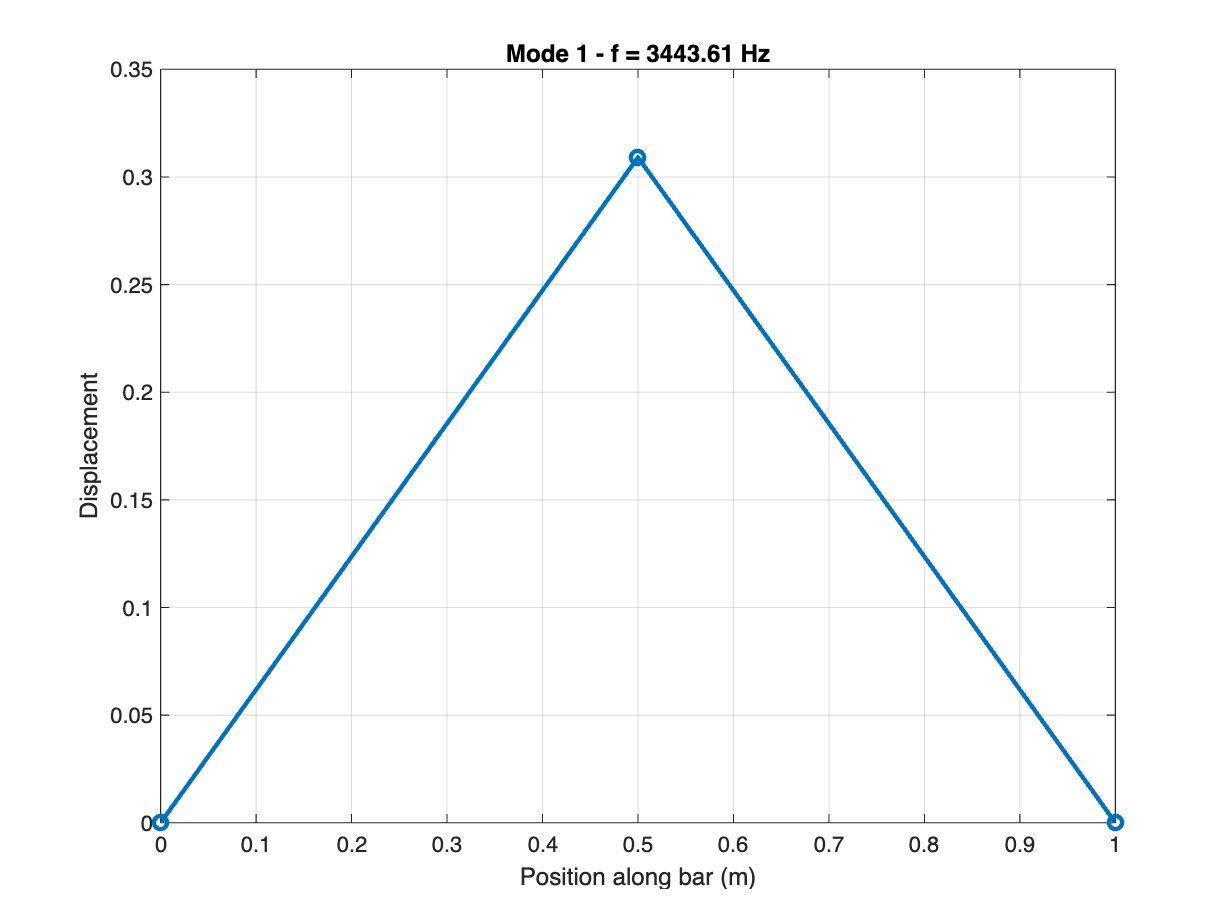

Number of elements: 2


Natural frequencies (Hz):


   1.0e+03 *

    3.3246
    6.8872
    9.2238



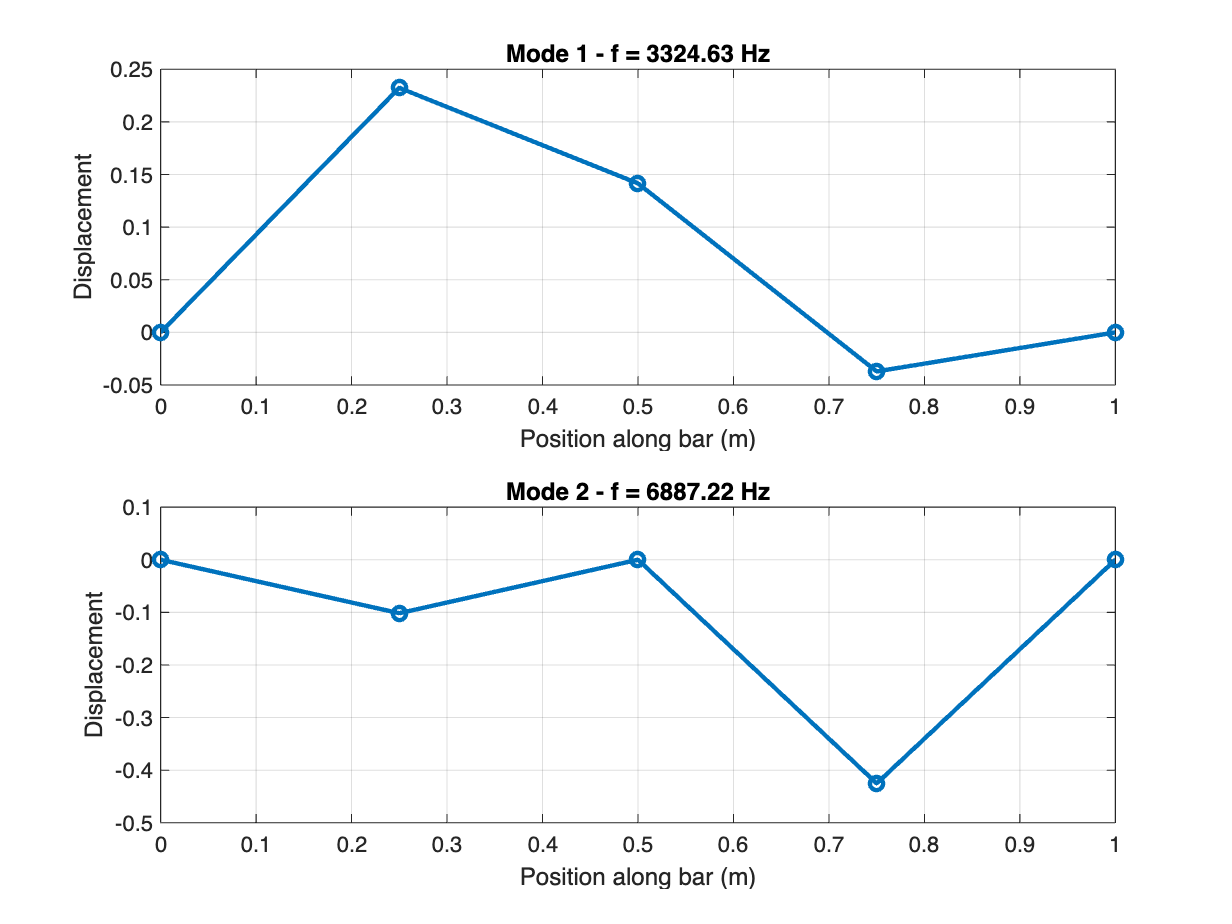

Number of elements: 4


Natural frequencies (Hz):


   1.0e+04 *

    0.3768
    0.6649
    0.8136
    1.3774
    1.6161
    1.8448
    2.1869



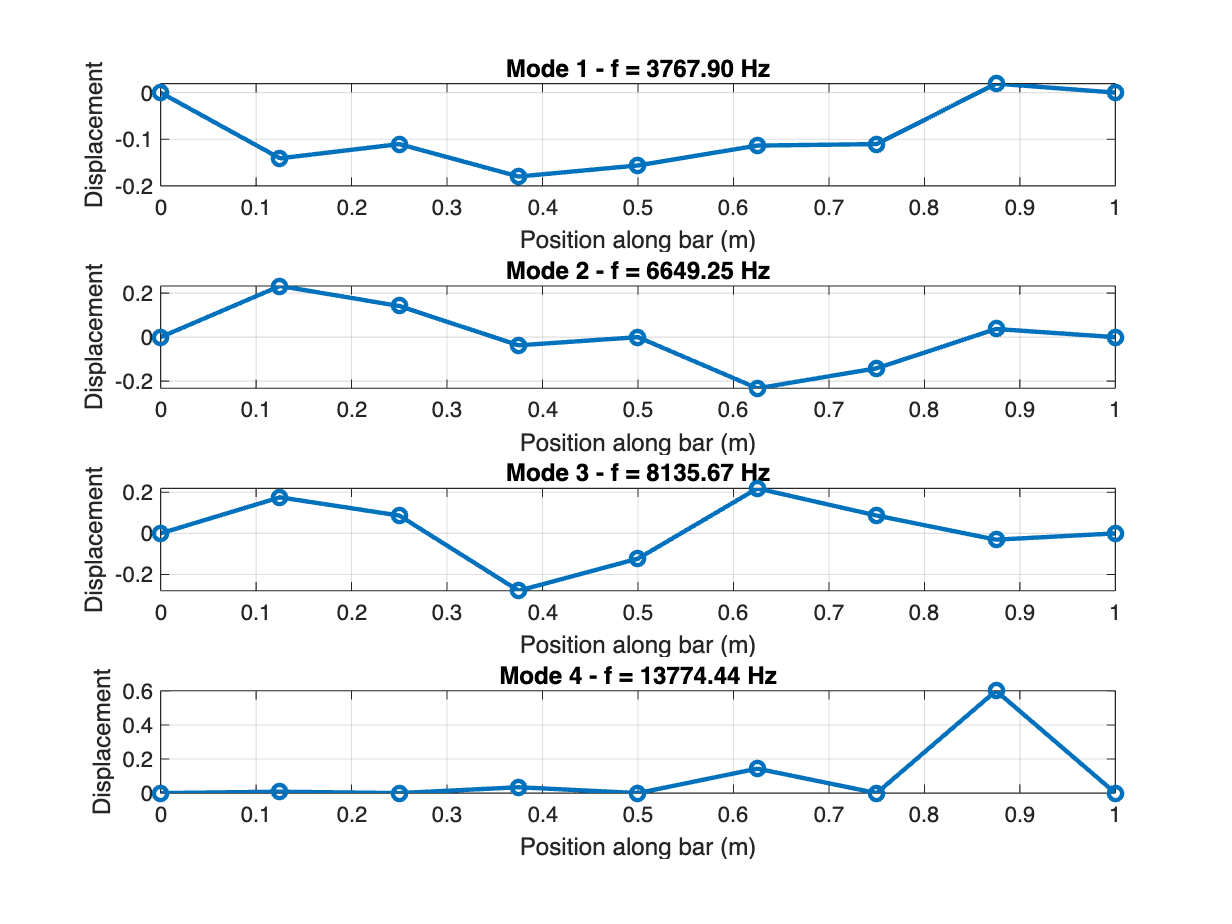

Number of elements: 8


Natural frequencies (Hz):


   1.0e+04 *

    0.3875
    0.7536
    1.0746
    1.3299
    1.5116
    1.6271
    1.6898
    2.7549
    3.1290
    3.2321
    3.4173
    3.6895
    4.0280
    4.3738
    4.6394



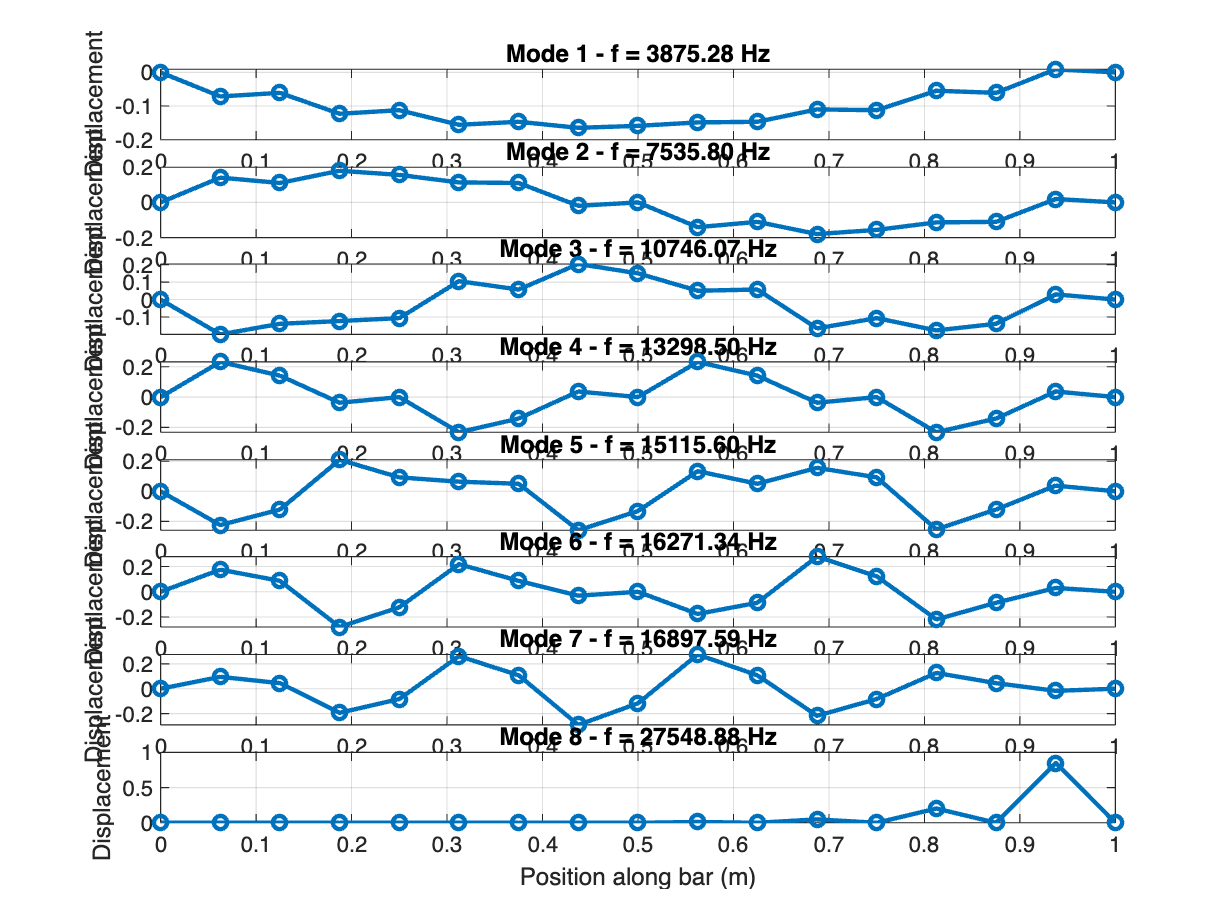

Number of elements: 16


Natural frequencies (Hz):


   1.0e+04 *

    0.3901
    0.7751
    1.1493
    1.5072
    1.8424
    2.1492
    2.4227
    2.6597
    2.8594
    3.0231
    3.1536
    3.2543
    3.3286
    3.3795
    3.4092
    5.5098
    6.2086
    6.2579
    6.3421
    6.4643
    6.6275
    6.8345
    7.0860
    7.3791
    7.7065
    8.0559
    8.4100
    8.7475
    9.0449
    9.2787
    9.4285



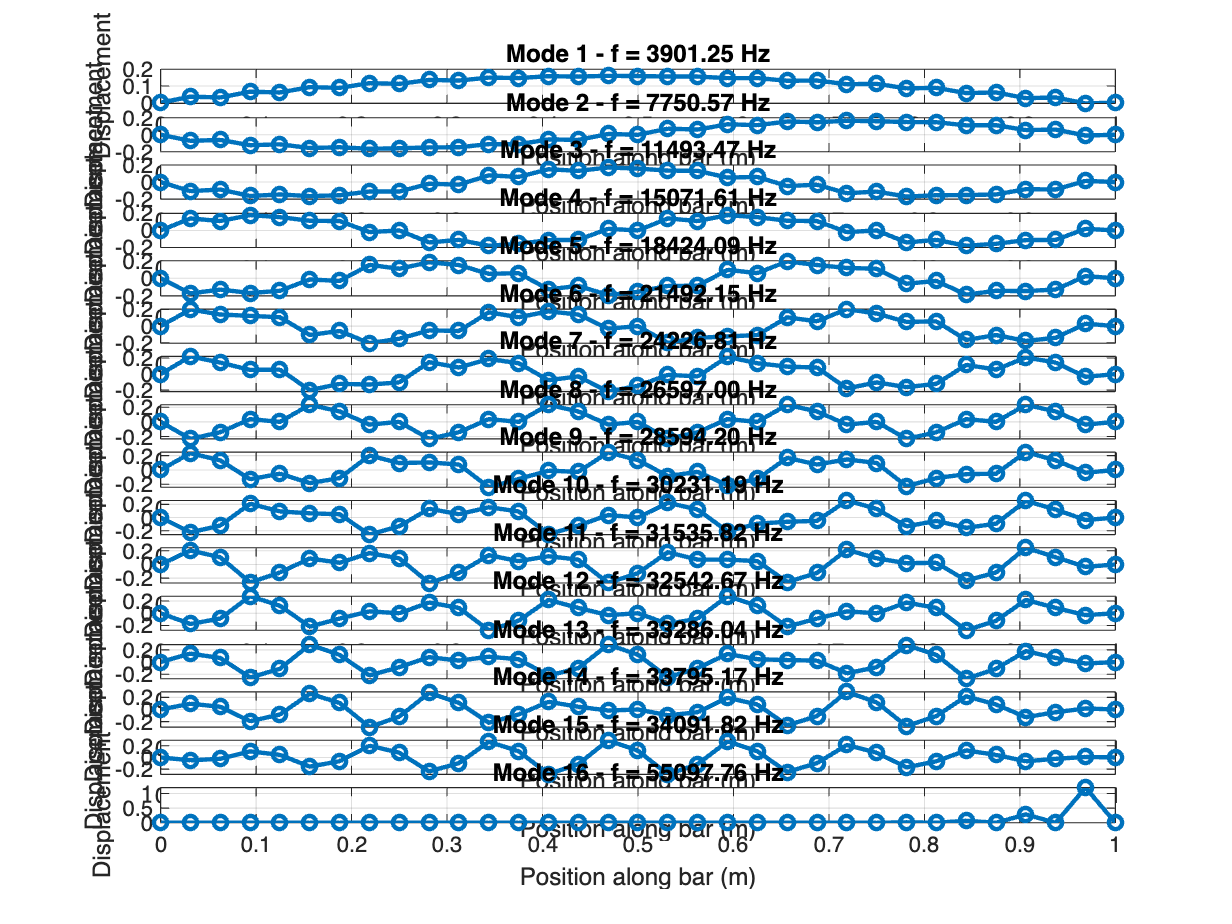

clc; clear; close all;

% Material and geometric properties
l = 1;                  % Length of the bar (m)
A = 0.01;               % Cross-sectional area (m^2)
E = 210e9;              % Elastic modulus (Pa)
rho = 7850;             % Density (kg/m^3)

% Number of elements to analyze
num_elements = [1, 2, 4, 8, 16];

for n = num_elements
    [K, M, nodes] = build_matrices(n, l, A, E, rho);
    
    % Solve the eigenvalue problem
    [V, D] = eig(K, M);
    freqs = sqrt(diag(D)) / (2 * pi);  % Convert to Hz

    % Sort frequencies and mode shapes
    [freqs, idx] = sort(freqs);
    V = V(:, idx);
    
    % Display results
    fprintf('Number of elements: %d\n', n);
    fprintf('Natural frequencies (Hz):\n');
    disp(freqs);  % Show frequencies

    % Plot mode shapes
    figure;
    for mode = 1:n
        subplot(n, 1, mode);
        plot(nodes, [0; V(:, mode); 0], '-o', 'LineWidth', 2);
        title(['Mode ', num2str(mode), ' - f = ', num2str(freqs(mode), '%.2f'), ' Hz']);
        xlabel('Position along bar (m)');
        ylabel('Displacement');
        grid on;
    end
end


% Function to build global stiffness and mass matrices
function [K, M, nodes] = build_matrices(n, l, A, E, rho)
    % Number of nodes
    num_nodes = 2 * n + 1;  
    nodes = linspace(0, l, num_nodes)';  

    % Element properties
    [Ke, Me] = build_elementary_matrices(n, l, A, E, rho);

    % Global matrices
    K = zeros(num_nodes, num_nodes);
    M = zeros(num_nodes, num_nodes);

    % Assembly
    for i = 1:n
        idx = 2 * i - 1 : 2 * i + 1;
        K(idx, idx) = K(idx, idx) + Ke;
        M(idx, idx) = M(idx, idx) + Me;
    end

    % Remove rigid body motion (free-free condition)
    K = K(2:end-1, 2:end-1);
    M = M(2:end-1, 2:end-1);
end

% Function to build local stiffness and mass matrices
function [Ke, Me] = build_elementary_matrices(n, l, A, E, rho)
    length_element = l / n; 
    jacobian_det = length_element / 2;
    jacobian_inv = 1/jacobian_det;
    
    syms xi
    Ha = [0.5 * xi * (xi - 1), 0.5 * xi * (xi + 1), 1 - xi^2];
    Ba = diff(Ha, xi);

    Ke = E * A * int(transpose(Ba * jacobian_inv) * Ba * jacobian_inv * jacobian_det, xi, [-1,1]);
    Me = rho * A * int(transpose(Ha) * Ha * jacobian_det, xi, [-1,1]); 
end

$$Ke = \left(\begin{array}{ccc} \frac{7}{3} & \frac{1}{3} & -\frac{8}{3}\\ \frac{1}{3} & \frac{7}{3} & -\frac{8}{3}\\ -\frac{8}{3} & -\frac{8}{3} & \frac{16}{3} \end{array}\right)$$

$$Me = \left(\begin{array}{ccc} \frac{2}{15} & -\frac{1}{30} & \frac{1}{15}\\ -\frac{1}{30} & \frac{2}{15} & \frac{1}{15}\\ \frac{1}{15} & \frac{1}{15} & \frac{8}{15} \end{array}\right)$$